# Analyzing and Visualizing Open Precipitation Data

Authors: Kostas Leptokaropoulos and Shubo Chakrabarti

*Copyright 2024 - 2024 The MathWorks, Inc.  *

## Introduction

**Public Data: **Many public databases have been created for the purposes of making data freely accessible to the scientific community. A best practice is to assign a unique identifier to a dataset, so that it is discoverable. A common form of a unique identifier is a [Digital Object Identifier or DOI](https://en.wikipedia.org/wiki/Digital_object_identifier)® which points to the data. 

**Access Public Data:** To access and process public data, you can use several routes. 

- Download data files to your local machine and work with them in MATLAB®. 

- Access data directly via an API. MATLAB's function that [import data from NetCDF files](https://www.mathworks.com/help/matlab/network-common-data-form.html) from RESTful API used by many portals.

- If the portal offers only Python® bindings, [call Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html).

**Data formats:** MATLAB supports a broad range of data formats

- There is a wide range of scientific data formats that can be [natively read in MATLAB](https://www.mathworks.com/help/matlab/scientific-data.html). They include NetCDF, HDF5 and GRIB as well as more specialized data formats. 

- In addition, the [Mapping Toolbox™](https://uk.mathworks.com/products/mapping.html) contains [built-in functions](https://www.mathworks.com/help/map/file-import-and-export.html) to read data from many online data repositories in standard geo-data formats.

- Sometimes data import functions may be [written by the Geoscience community](https://uk.mathworks.com/matlabcentral/fileexchange/?category%5B%5D=overview%2Fsciences1689.support%2Fearth-oce840&q=data+read), and published on the MATLAB [File Exchange](https://uk.mathworks.com/matlabcentral/fileexchange/?category%5B%5D=overview%2Fsciences1689.support%2Fearth-oce840) - a portal for community contributions in MATLAB. All community contributions are covered by open source licenses, which means they can be re-used, modified or added to. Exact terms and conditions depend on the licenses used by the author.  

## Data and Resources

In this example, we use data covered by permissive license, (i.e., the [Creative Commons Attribution 4.0 International License](https://creativecommons.org/licenses/by/4.0/deed.en) - CC BY 4.0). It is important for Open Science to have such data since under CC BY 4.0 license you are free to share, copy, redistribute and adapt the material as long as you give appropriate credit, provide a link to the license, and indicate if any changes were made.

We access global climate data from the WCRP CMIP6 (World Climate Research Programme Coupled Intercomparison Project - Phase 6), which are located at:  [**https://esgf-data.dkrz.de/search/cmip6-dkrz/**.](https://esgf-data.dkrz.de/search/cmip6-dkrz)

The Data Space is hosted by the [German Climate Computer Center](https://www.dkrz.de/en) (DKRZ) and the [Infrastructure for the European Network for Earth System Modelling](https://is.enes.org/) (IS-ENES), as a part of the global [Earth System Grid Federation](https://esgf.llnl.gov/) (ESGF).  

The user can apply multiple filters and preferences for a large variety of climate parameters, such as see ice thickness, air pressure, phytoplankton mass concentration, etc, provided by different sources. In our example we used the following filtering:

- CF Standard name: precipitation flux

- Frequency: day

- Nominal Resolution: 10km, 25km

Make sure to check the box  *"Show all Replicas*".

**Example links** for the data from [ESGF MetaGrid (llnl.gov)](https://esgf-dev1.llnl.gov/search):

- data [Link](https://esgf-dev1.llnl.gov/search?project=CMIP6&activeFacets=%7B%22institution_id%22%3A%22AS-RCEC%22%2C%22experiment_id%22%3A%22highresSST-present%22%2C%22variant_label%22%3A%22r1i1p1f1%22%2C%22grid_label%22%3A%22gn%22%2C%22frequency%22%3A%22day%22%2C%22variable_id%22%3A%22pr%22%2C%22source_id%22%3A%22HiRAM-SIT-HR%22%7D&textInputs=%5B%22HighResMIP%22%2C%22CMIP6%2FHighResMIP%2FAS-RCEC%2FHiRAM-SIT-HR%2FhighresSST-present%2Fr1i1p1f1%2Fday%2Fpr%2Fgn%2Fv20210713%2Fpr_day_HiRAM-SIT-HR_highresSST-present_r1i1p1f1_gn_19530101-19531231.nc%22%5D)  (1950 - 2014); e.g., [data 19530101-19531231](https://esgf-data1.llnl.gov/thredds/dodsC/css03_data/CMIP6/HighResMIP/AS-RCEC/HiRAM-SIT-HR/highresSST-present/r1i1p1f1/day/pr/gn/v20210713/pr_day_HiRAM-SIT-HR_highresSST-present_r1i1p1f1_gn_19530101-19531231.nc.html)

- data [Link](https://esgf-dev1.llnl.gov/search?project=CMIP6&activeFacets=%7B%22institution_id%22:%22AS-RCEC%22,%22experiment_id%22:%22highresSST-future%22,%22variant_label%22:%22r1i1p1f1%22,%22grid_label%22:%22gn%22,%22frequency%22:%22day%22,%22variable_id%22:%22pr%22,%22source_id%22:%22HiRAM-SIT-HR%22%7D&textInputs=%5B%22HighResMIP%22,%22CMIP6/HighResMIP/AS-RCEC/HiRAM-SIT-HR/highresSST-present/r1i1p1f1/day/pr/gn/v20210713/pr_day_HiRAM-SIT-HR_highresSST-present_r1i1p1f1_gn_19530101-19531231.nc%22%5D)  (2015 - 2050); e.g., [data 20450101-20451231](https://esgf-data1.llnl.gov/thredds/dodsC/css03_data/CMIP6/HighResMIP/AS-RCEC/HiRAM-SIT-HR/highresSST-future/r1i1p1f1/day/pr/gn/v20210707/pr_day_HiRAM-SIT-HR_highresSST-future_r1i1p1f1_gn_20450101-20451231.nc.html)

`Data Acknowledgment Statement`` (see `[`CMIP6 terms of use`](https://pcmdi.llnl.gov/CMIP6/TermsOfUse/TermsOfUse6-2.html)`):`

`“We acknowledge the World Climate Research Programme, which, through its Working Group on Coupled Modelling, coordinated and promoted CMIP6. We thank the climate modeling groups for producing and making available their model output, the Earth System Grid Federation (ESGF) for archiving the data and providing access, and the multiple funding agencies who support CMIP6 and ESGF. We used the CMIP6 model data produced by the Research Center for Environmental Changes, Academia Sinica, Taiwan (AS-RCEC), which is licensed under a Creative Commons Attribution 4.0 International License (CC BY 4.0; `[`https://creativecommons.org/licenses/`](https://creativecommons.org/licenses/)`). `

`Further information about this data can be found via the further_info_url (recorded as a "Global Attributes: License" in these .nc files). The data producers and data providers make no warranty, either express or implied, including, but not limited to, warranties of merchantability and fitness for a particular purpose. All liabilities arising from the supply of the information (including any liability arising in negligence) are excluded to the fullest extent permitted by law.”`

## Import Data from the web

clearvars; clc; close all

You can read any 2 data sets from the example links indicated above, one imported as "URLpast" and a subsequent one as "URLproj".

There are a bunch of [functions that you can use to interact with NetCDF files](https://uk.mathworks.com/help/matlab/network-common-data-form.html).

% read NETCDF data from the web
  URLpast = "https://esgf-data1.llnl.gov/thredds/dodsC/css03_data/CMIP6/HighResMIP/AS-RCEC/HiRAM-SIT-HR/highresSST-present/r1i1p1f1/day/pr/gn/v20210713/pr_day_HiRAM-SIT-HR_highresSST-present_r1i1p1f1_gn_19530101-19531231.nc";
  URLproj = "https://esgf-data1.llnl.gov/thredds/dodsC/css03_data/CMIP6/HighResMIP/AS-RCEC/HiRAM-SIT-HR/highresSST-future/r1i1p1f1/day/pr/gn/v20210707/pr_day_HiRAM-SIT-HR_highresSST-future_r1i1p1f1_gn_20430101-20431231.nc";


Read the precipitation flux as "Variable"

ncdisp(URLpast)

Source:
           https://esgf-data1.llnl.gov/thredds/dodsC/css03_data/CMIP6/HighResMIP/AS-RCEC/HiRAM-SIT-HR/highresSST-present/r1i1p1f1/day/pr/gn/v20210713/pr_day_HiRAM-SIT-HR_highresSST-present_r1i1p1f1_gn_19530101-19531231.nc
Format:
           classic
Global Attributes:
           Conventions                    = 'CF-1.7 CMIP-6.2'
           activity_id                    = 'HighResMIP'
           branch_method                  = 'no parent'
           contact                        = 'Dr. Chia-Ying Tu (cytu@gate.sinica.edu.tw)'
           creation_date                  = '2021-07-01T18:11:53Z'
           data_specs_version             = '01.00.32'
           experiment                     = 'forced atmosphere experiment for 1950-2014'
           experiment_id                  = 'highresSST-present'
           external_variables             = 'areacella'
           forcing_index                  = 1
           frequency                      = 'day'
           further_info_url     

ncdisp(URLproj)

Source:
           https://esgf-data1.llnl.gov/thredds/dodsC/css03_data/CMIP6/HighResMIP/AS-RCEC/HiRAM-SIT-HR/highresSST-future/r1i1p1f1/day/pr/gn/v20210707/pr_day_HiRAM-SIT-HR_highresSST-future_r1i1p1f1_gn_20430101-20431231.nc
Format:
           classic
Global Attributes:
           Conventions                    = 'CF-1.7 CMIP-6.2'
           activity_id                    = 'HighResMIP'
           branch_method                  = 'standard'
           branch_time_in_child           = 24472
           branch_time_in_parent          = 24472
           contact                        = 'Dr. Chia-Ying Tu (cytu@gate.sinica.edu.tw)'
           creation_date                  = '2021-06-29T09:10:23Z'
           data_specs_version             = '01.00.32'
           experiment                     = 'forced atmosphere experiment for 2015-2050 using SST/sea-ice derived from CMIP5 RCP8.5 simulations and a scenario as close to RCP8.5 as possible within CMIP6'
           experiment_id             

Variable = "pr"; 

## Read and filter Geospatial Data

read longitude and latitude from the .nc file

lon = double(ncread(URLpast,'lon')); 
lat = double(ncread(URLpast,'lat')); 

#### Filter Data in Time and Space

Select boundaries of a rectangular area

%minimum and maximum longitude
minlon = 25;maxlon = 40; % set values from 0 to 360
%minimum and maximum latitude
minlat = 35;maxlat = 50; % set values from -90 to 90

Select first day and number of days after the first *(their sum must not exceed 365)*

starttime = 100;counttime = 190;% set values from 1 to 365

Find the indexes of longitude and latitude that correspond to the selected geographical boundaries

indlon = find(lon>=minlon & lon<=maxlon);
indlat = find(lat>=minlat & lat<=maxlat);

startlon=indlon(1);countlon=numel(indlon);
startlat=indlat(1);countlat=numel(indlat);

## Import Filtered Data

Import longitude, latitude, time and precipitation values for past and future data, as constrained in the previous section.

lat = double(ncread(URLpast,'lat',startlat,countlat));
lon = double(ncread(URLpast,'lon',startlon,countlon));
tpast = double(ncread(URLpast,'time',starttime,counttime));
tproj = double(ncread(URLproj,'time',starttime,counttime));
Varpast = double(ncread(URLpast,Variable,[startlon startlat starttime],[countlon countlat counttime]));
Varproj = double(ncread(URLproj,Variable,[startlon startlat starttime],[countlon countlat counttime]));

read the precipitation unit from the .nc file

unit = ncreadatt(URLpast,'pr','original_units');

### Convert units from sec-1 to day-1

 Varpast = Varpast*86400;
 Varproj = Varproj*86400;
 newunit = "kg m^-^2 day^-^1"

newunit = "kg m^-^2 day^-^1"

### Calculate dates 

calculate date vectors, as days passed since the reference date in the .nc file

Tpast = datetime('1948-1-1')+tpast,Tproj = datetime('1948-1-1')+tproj

Tpast = 190×1 datetime array
   10-Apr-1953 12:00:00
   11-Apr-1953 12:00:00
   12-Apr-1953 12:00:00
   13-Apr-1953 12:00:00
   14-Apr-1953 12:00:00
   15-Apr-1953 12:00:00
   16-Apr-1953 12:00:00
   17-Apr-1953 12:00:00
   18-Apr-1953 12:00:00
   19-Apr-1953 12:00:00
   20-Apr-1953 12:00:00
   21-Apr-1953 12:00:00
   22-Apr-1953 12:00:00
   23-Apr-1953 12:00:00
   24-Apr-1953 12:00:00
   25-Apr-1953 12:00:00
   26-Apr-1953 12:00:00
   27-Apr-1953 12:00:00
   28-Apr-1953 12:00:00
   29-Apr-1953 12:00:00
   30-Apr-1953 12:00:00
   01-May-1953 12:00:00
   02-May-1953 12:00:00
   03-May-1953 12:00:00
   04-May-1953 12:00:00
   05-May-1953 12:00:00
   06-May-1953 12:00:00
   07-May-1953 12:00:00
   08-May-1953 12:00:00
   09-May-1953 12:00:00


Tproj = 190×1 datetime array
   10-Apr-2043 12:00:00
   11-Apr-2043 12:00:00
   12-Apr-2043 12:00:00
   13-Apr-2043 12:00:00
   14-Apr-2043 12:00:00
   15-Apr-2043 12:00:00
   16-Apr-2043 12:00:00
   17-Apr-2043 12:00:00
   18-Apr-2043 12:00:00
   19-Apr-2043 12:00:00
   20-Apr-2043 12:00:00
   21-Apr-2043 12:00:00
   22-Apr-2043 12:00:00
   23-Apr-2043 12:00:00
   24-Apr-2043 12:00:00
   25-Apr-2043 12:00:00
   26-Apr-2043 12:00:00
   27-Apr-2043 12:00:00
   28-Apr-2043 12:00:00
   29-Apr-2043 12:00:00
   30-Apr-2043 12:00:00
   01-May-2043 12:00:00
   02-May-2043 12:00:00
   03-May-2043 12:00:00
   04-May-2043 12:00:00
   05-May-2043 12:00:00
   06-May-2043 12:00:00
   07-May-2043 12:00:00
   08-May-2043 12:00:00
   09-May-2043 12:00:00


Tpast.Format = 'dd-MMM-uuuu';Tproj.Format = 'dd-MMM-uuuu';
Tpast_str = string(Tpast);
Tproj_str = string(Tproj);


## Select a day to visualize precipitation data

close all

Select a day


t1 = Tpast_str(6);inx = Tpast_str == t1;

Create a grid with precipitation values

[lat1,lon1] = meshgrid(lat,lon);
Var1past = Varpast(:,:,inx);
Var1proj = Varproj(:,:,inx);
mV = min([min(Var1past(:)),min(Var1proj(:))])

mV = -9.0042e-16

MV = max([max(Var1past(:)),max(Var1proj(:))])

MV = 51.4354

Customize colormap limits to the selected data


  CBmin = -9.00419266706534e-16;
  CBmax = 51.43537279218435;

## Visualize and compare past and projected data

Create a 2 frame figure. Plot the past data in the left frame and the projected data in the right frame. Add the coastlines in both figures. The text displayed in the figure (title, colorbar) is also directly imported from the .nc file metadata and the parameter values we have set.

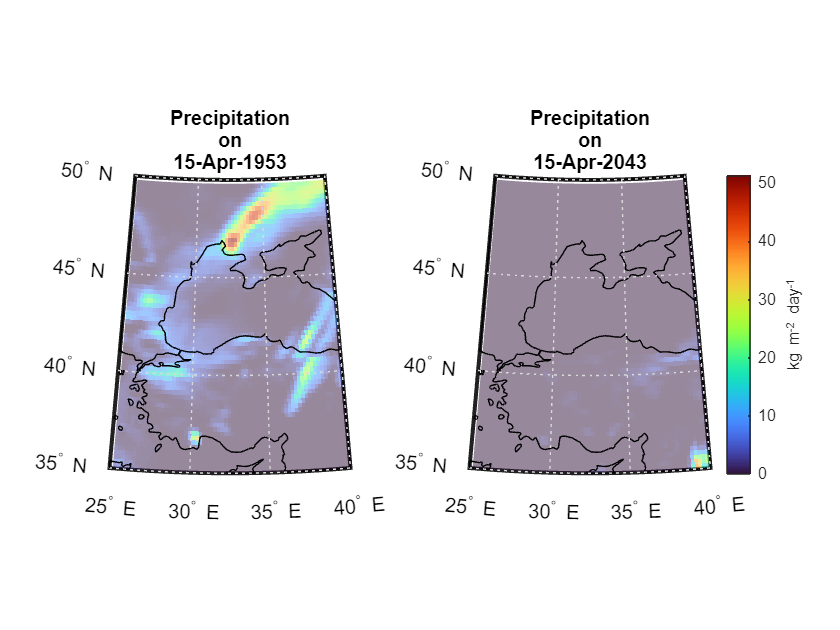

tiledlayout(1,2)
nexttile % past 
worldmap([minlat maxlat],[minlon maxlon])
geoshow(lat1,lon1,Var1past,'DisplayType','texturemap','FaceAlpha',0.5);
geoshow('landareas.shp','EdgeColor','black','FaceColor','none')
title([ncreadatt(URLpast,Variable,'long_name'),'on',t1])
  clim([CBmin CBmax])

nexttile %projection
worldmap([minlat maxlat],[minlon maxlon])
geoshow(lat1,lon1,Var1proj,'DisplayType','texturemap','FaceAlpha',0.5);
geoshow('landareas.shp','EdgeColor','black','FaceColor','none')
 cb = colorbar; % display colorbar
 cb.Location='eastoutside';
 cb.Label.String = (newunit);
title([ncreadatt(URLproj,Variable,'long_name'),'on',Tproj_str(inx)])
  clim([CBmin CBmax])
 
 colormap turbo

## Some Stats!

In this section a comparison is performed between the past and projected data. 

- First, the precipitation time series (daily, solid lines; cumulative, dashed lines) are plotted in the same plot for direct comparison.

- Then, [box charts](https://uk.mathworks.com/help/matlab/ref/boxchart.html) are generated to show the daily sum average precipitation values distribution (including the outliers)

- Finally, 3 Hypothesis Tests are performed to evaluate the statistical significance of the results from the comparison of the past and projected precipitation:

 a) The [Wilcoxon rank sum test](https://uk.mathworks.com/help/stats/ranksum.html): Tests the null hypothesis that past and projected data are samples from continuous distributions with equal medians, against the alternative that they are not. 

b) The [2 sample t-test](https://uk.mathworks.com/help/stats/ttest2.html): Tests the null hypothesis that past and projected data come from independent random samples from normal distributions with equal means and equal but unknown variances. The alternative hypothesis is that the past and projected data comes from populations with unequal means. 

c) The 2 sample [Kolmogorov - Smirnov test](https://uk.mathworks.com/help/stats/kstest2.html): Tests the null hypothesis that that past and projected data are from the same continuous distribution against the alternative hypothesis that they are from different continuous distributions. 

### Compare incremental and cumulative precipitation

N = numel(tpast)

N = 190

Select number of days (between 1 and N)

T1 = Tpast_str(1);inx1 = Tpast_str == T1;n1 = find(inx1);
T2 = Tpast_str(190);inx2 = Tpast_str == T2;n2 = find(inx2);
n = n2 - n1 +1;
if n2<=n1;error('End date (n2) should be greater than start date (n1)');end


### Generate Daily/Cumulative Plots and Box Charts

Boxp1 = zeros(size(n,1));Boxp2 = zeros(size(n,1));cou=1;
for i=n1:n2
Boxp1(cou) = sum(Varpast(:,:,i),"all");
Boxp2(cou) = sum(Varproj(:,:,i),"all");
cou=cou+1;
end


 Daily and Cumulative plots 

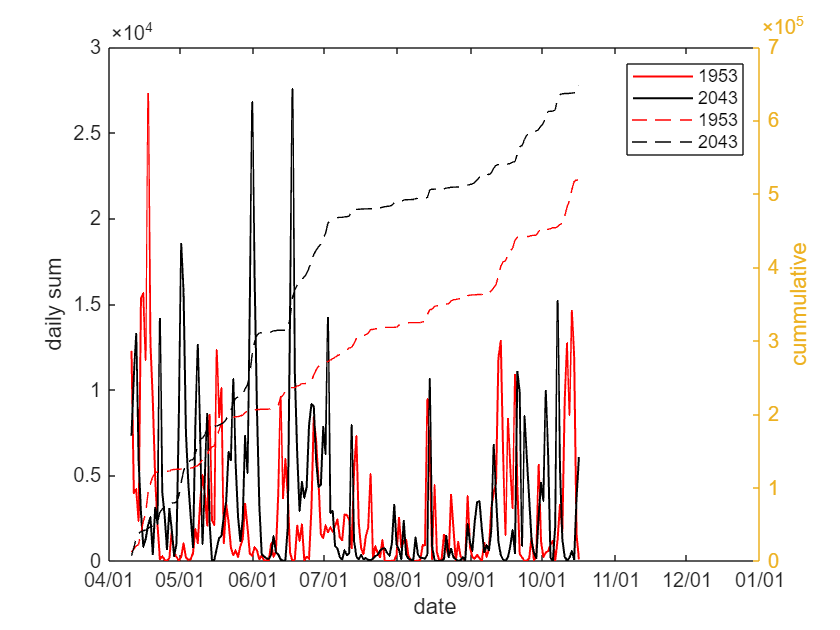

figure
plot(Tpast(n1:n2),Boxp1,'r-',Tpast(n1:n2),Boxp2,'k-',LineWidth=1);datetick('x',6);ylabel('daily sum');xlabel('date');
hold on
yyaxis right;plot(Tpast(n1:n2),cumsum(Boxp1),'r--',Tpast(n1:n2),cumsum(Boxp2),'k--');datetick('x',6);ylabel('cummulative');xlabel('date');
legend(num2str(year(Tpast(1))),num2str(year(Tproj(1))),num2str(year(Tpast(1))),num2str(year(Tproj(1))))

Box charts

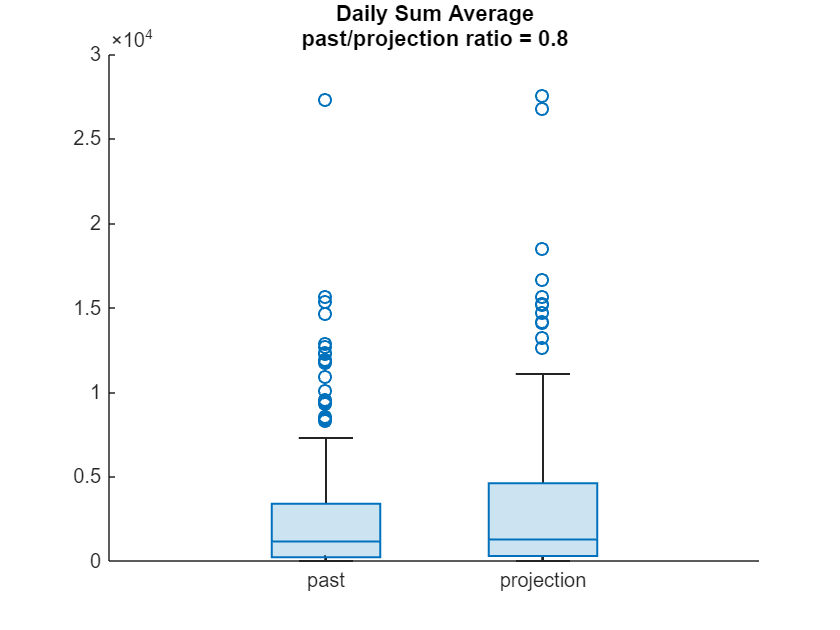

figure
group = categorical([repmat("past", size(Boxp1));repmat("projection", size(Boxp2))]);
boxchart([Boxp1',Boxp2']);xticklabels({'past','projection'});
title(["Daily Sum Average","past/projection ratio = "+num2str(sum(Boxp1)/sum(Boxp2),'%7.1f')])

### Perform Statistical Tests

[p.Wilcoxon,h.Wilcoxon] = ranksum(Boxp1,Boxp2); % null hypothesis, h0, equal medians
[h.ttest2,p.ttest2] = ttest2(Boxp1,Boxp2); % null hypothesis, h0, equal means
[h.kstest2,p.kstest2] = kstest2(Boxp1,Boxp2); % null hypothesis, h0, samples come from the same distribution
h.ttest2 = logical(h.ttest2);

if h.Wilcoxon==0;disp(['>> The Wilcoxon rank sum test FAILS to reject the hypothesis of equal medians at ' ,num2str(p.Wilcoxon) ' significance'])
else; disp(['>> The Wilcoxon rank sum test REJECTS the hypothesis of equal medians at ',num2str(p.Wilcoxon), ' significance'])
end

>> The Wilcoxon rank sum test FAILS to reject the hypothesis of equal medians at 0.17606 significance



if h.ttest2==0;disp(['>> The 2-sample t-test FAILS to reject the hypothesis of equal means at ' ,num2str(p.ttest2) ' significance'])
else; disp(['>> The 2-sample t-test REJECTS the hypothesis of equal means at ',num2str(p.ttest2), ' significance'])
end

>> The 2-sample t-test FAILS to reject the hypothesis of equal means at 0.13235 significance



if h.kstest2==0;disp(['>> The 2-sample Kolmogorov-Smirnov test FAILS to reject the hypothesis that the two samples come from the same distribution at ' ,num2str(p.kstest2) ' significance'])
else; disp(['>> The 2-sample Kolmogorov-Smirnov test REJECTS the hypothesis that the two samples come from the same distribution at ',num2str(p.kstest2), ' significance'])
end

>> The 2-sample Kolmogorov-Smirnov test FAILS to reject the hypothesis that the two samples come from the same distribution at 0.22976 significance


## Publish reusable MATLAB code for reproducible results

To enable collaboration partners, reviewers and the community reuse your MATLAB code and reproduce your results.

- Publish your MATLAB code (eg: on GitHub) and generate a [DOI](https://en.wikipedia.org/wiki/Digital_object_identifier) (digital object identifier) by [linking it to a DOI generating portal](https://docs.github.com/en/repositories/archiving-a-github-repository/referencing-and-citing-content) (e.g. [Figshare](https://help.figshare.com/article/how-to-connect-figshare-with-your-github-account#:~:text=You%20can%20get%20set%20up,where%20you'll%20authorise%20figshare.)®, [Zenodo](https://docs.github.com/en/repositories/archiving-a-github-repository/referencing-and-citing-content)®). Make your research output findable by including as much information as needed in the metadata. Document your code well explaining steps required to reproduce clearly and explicitly.

- Make sure you include a license for your code that specifies reuse and re-distribution rights for the code. Various open source licenses are [available](https://opensource.org/licenses/). BSD, MIT and Apache licenses are commonly used for open research software.

- [Link your GitHub repository to File Exchange](https://www.mathworks.com/matlabcentral/content/fx/about.html?s_tid=gn_mlc_fx_help#Why_GitHub) to make your MATLAB code available to MATLAB users via the Add-Ons button. 

            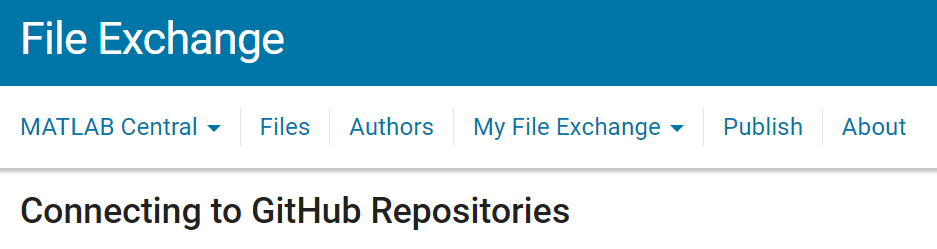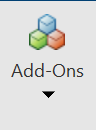

- Make your MATLAB code **interoperable**. MATLAB is [interoperable](https://www.mathworks.com/products/matlab/matlab-and-other-programming-languages.html) with several other languages including C, Fortran and Python. MATLAB can be directly called from Python using the [MATLAB Engine for Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html)® which is available as a PyPI® package and can be installed using the command `pip install matlab.engine` from Python. MATLAB code can also be [packaged as a Python library](https://www.mathworks.com/help/compiler_sdk/gs/create-a-python-application-with-matlab-code.html) and called from Python. Deep Learning models from other frameworks are [interoperable with MATLAB](https://www.mathworks.com/help/deeplearning/ug/interoperability-between-deep-learning-toolbox-tensorflow-pytorch-and-onnx.html) either using the [ONNX™ interface](https://www.mathworks.com/matlabcentral/fileexchange/67296-deep-learning-toolbox-converter-for-onnx-model-format) or via direct interfaces that exist, for example, for Pytorch® and Tensorflow™ models. 

          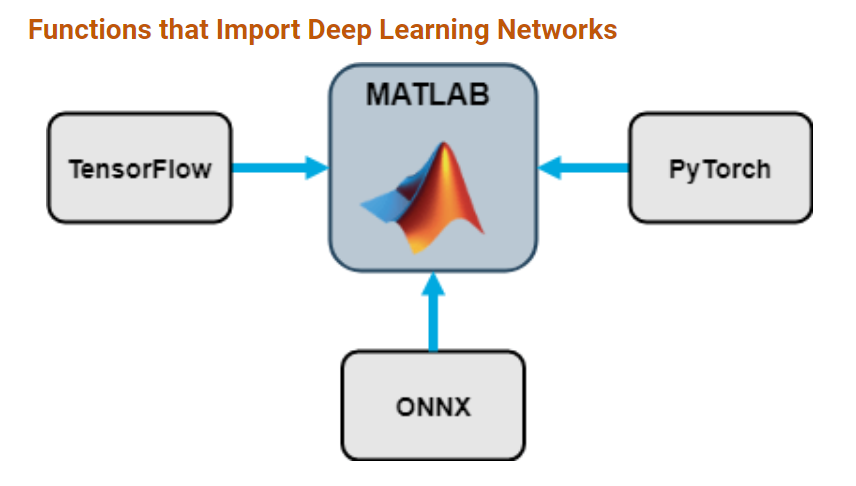

- MATLAB is interoperable with cloud architectures such as [JupyterHub](https://www.mathworks.com/products/reference-architectures/jupyter.html)® and MATLAB code can also be used within Jupyter Notebooks. Here is a link to a Jupyter® notebook of the same example used here. There is an official MATLAB kernel for Jupyter Notebooks - read about it [here](https://blogs.mathworks.com/matlab/2023/01/30/official-mathworks-matlab-kernel-for-jupyter-released/). **To easily convert a Live Script into a Jupyter® notebook use the **[`export`](https://uk.mathworks.com/help/matlab/ref/export.html)** function**.

          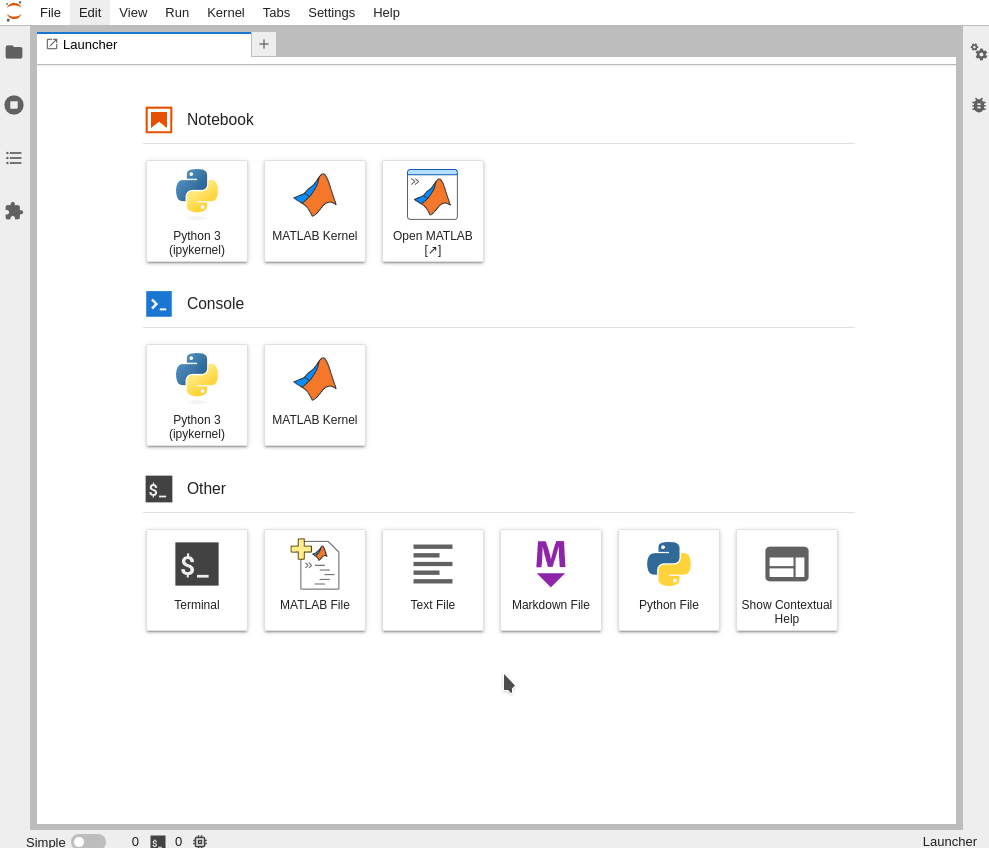

- Run your [MATLAB code on the browser directly from GitHub](https://www.mathworks.com/help/matlab/matlab_env/open-github-repositories-in-matlab-online.html). Copy and paste the GitHub repo address into [this app](https://www.mathworks.com/products/matlab-online/git.html). That will generate a command, which when pasted into your README, will create a "Open in MATLAB Online™" button on your GitHub repository. By clicking on this button, users will be able to run your code in the browser on MATLAB Online.

           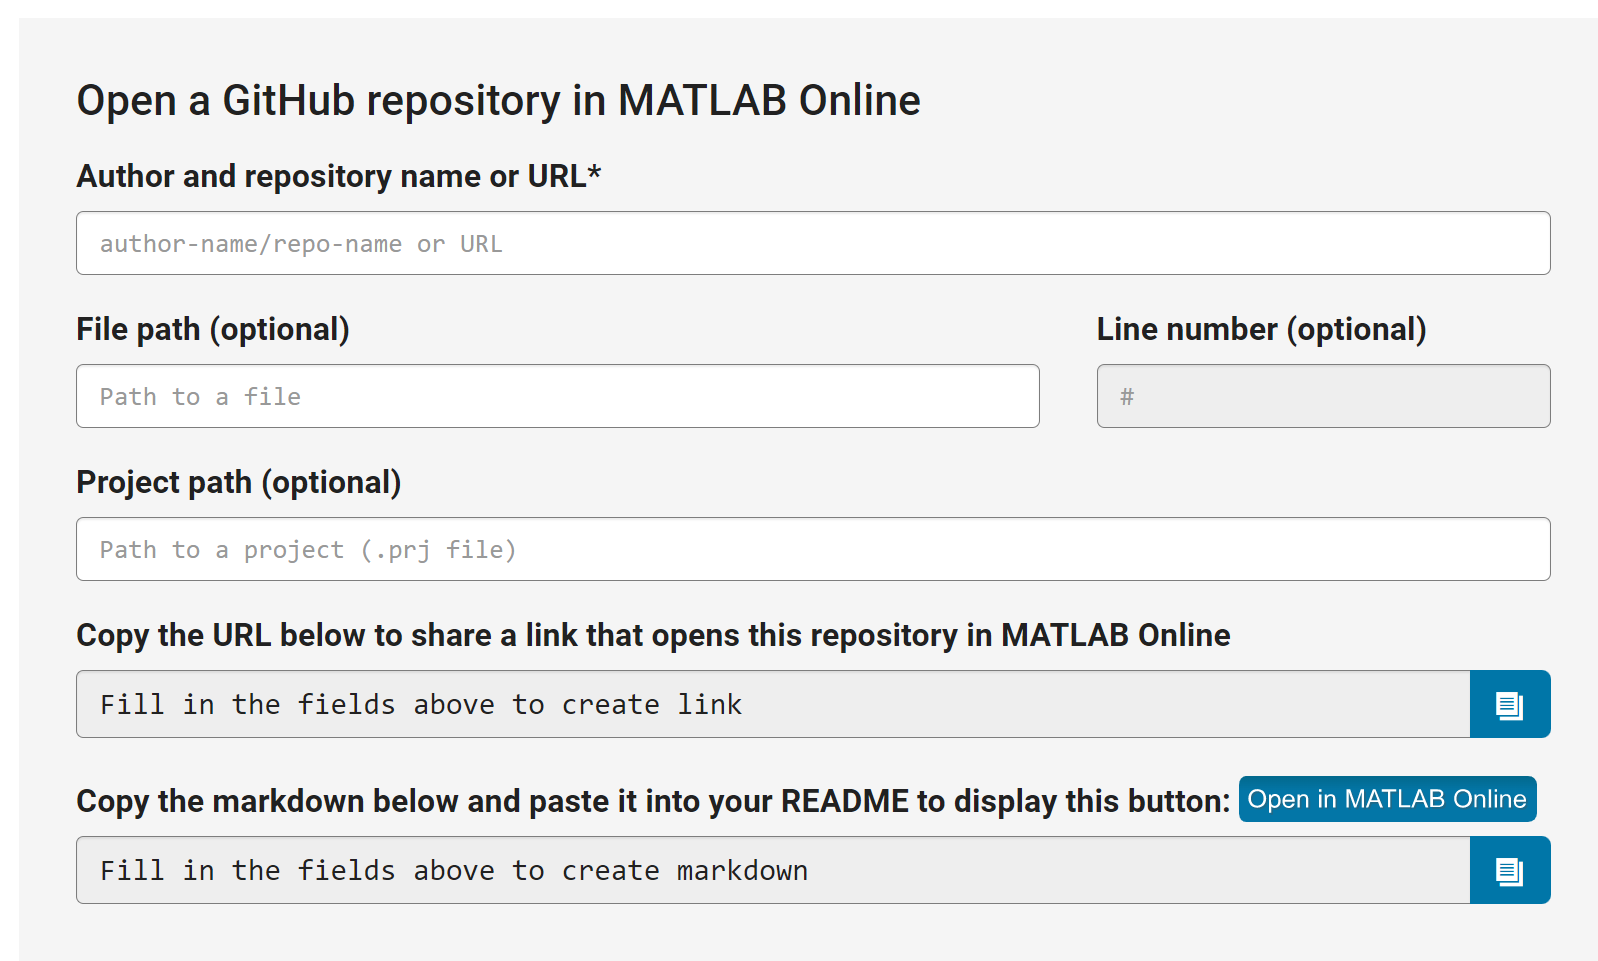

- Make your MATLAB code reproducible by using a reproducibility portals that supports MATLAB. One example is Code Ocean®. On Code Ocean, you can [upload your MATLAB code](https://help.codeocean.com/en/articles/1120384-which-toolboxes-are-included-with-matlab) including dependencies. Once uploaded, your code is tested and published as a Code Ocean "capsule" which can be run online or downloaded and run locally by users. Code Ocean also generates a DOI for your code capsule.  For Live Scripts, convert the `.mlx` file into e.g., a `.m` file, a `.html` or a.ipynb file using the [`export`](https://de.mathworks.com/help/matlab/ref/export.html) function for best results. Here is the DOI for the Code Ocean capsule of the this code. Read more about MATLAB on Code Ocean [here](https://blogs.mathworks.com/loren/2021/07/15/sharing-and-running-matlab-code-in-the-cloud/#H_795BB86B).

         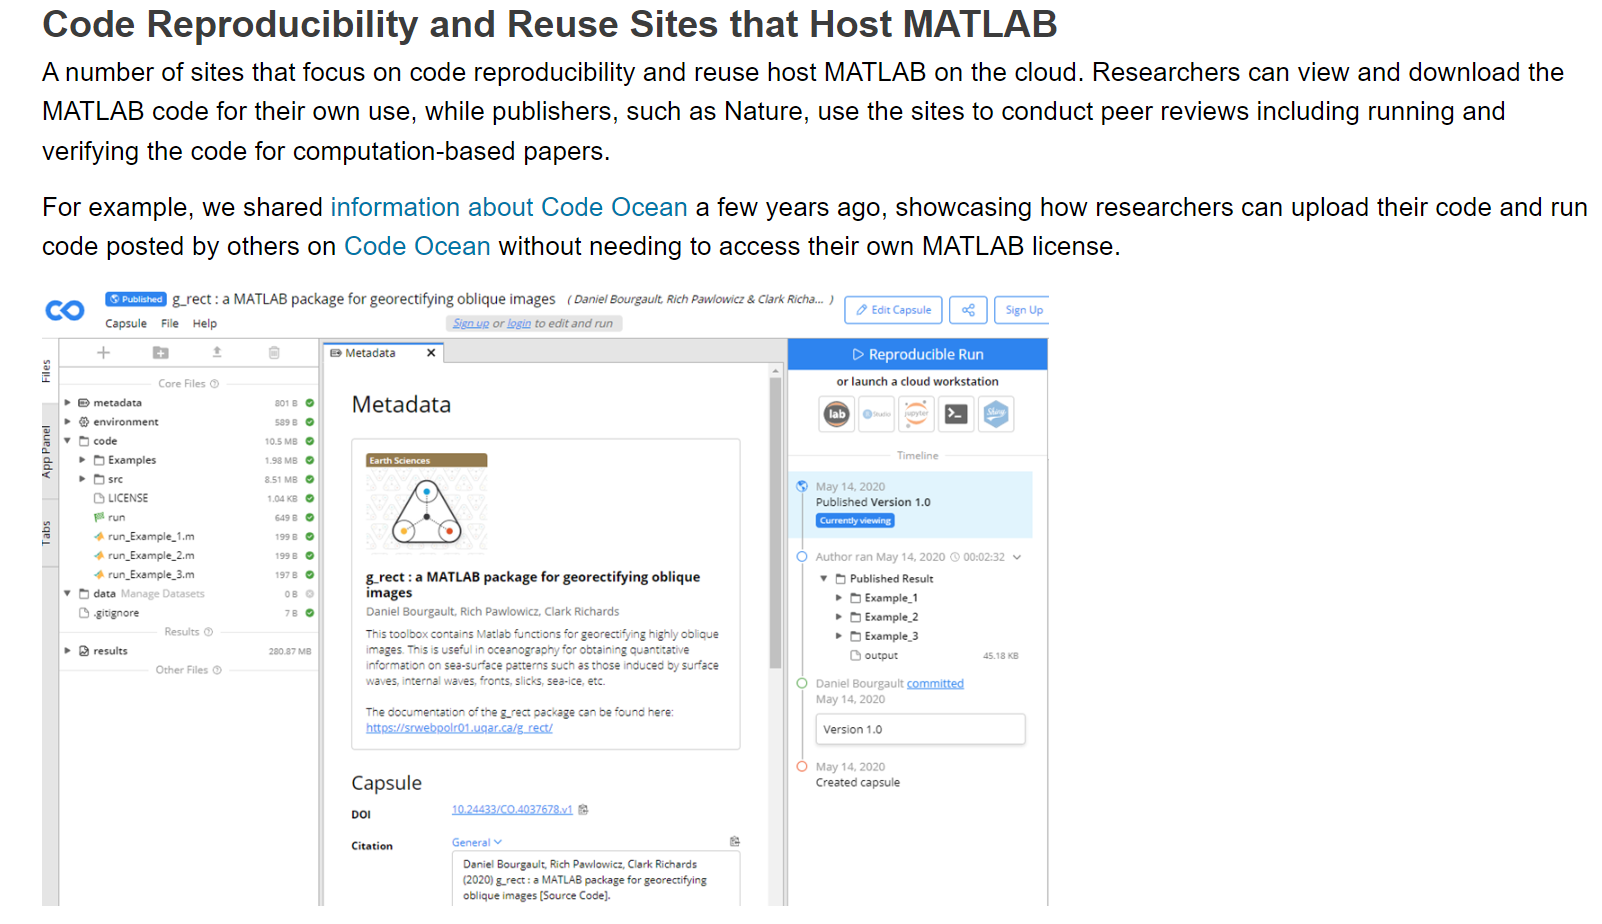

- **Warning**: Before making your code available on the cloud, make sure all dependencies including any data that is needed for your code to run is uploaded along with the code. Also make sure any path and/or filenames that refer to local directories are appropriately renamed.

- FAIR standards: FAIR is an acronym that stands for **F**indable, **A**ccessible, **I**nteroperable and **R**eproducible. It is an [accepted standard](https://www.nature.com/articles/s41597-022-01710-x) for research output (code, data) and is often required for your research results to be in [compliance with "Open Science" standards](https://research-and-innovation.ec.europa.eu/strategy/strategy-2020-2024/our-digital-future/open-science_en). Adhering to the above pointers helps in making your MATLAB code FAIR

*Copyright 2024 - 2024 The MathWorks, Inc.*